**(Task 1) Using the periodogram( ) function to get an idea of the PSD of the File:**

In order to use the periodogram( ) function to get some idea about the PSD of the signal, let us first extract or 'read' the signal using the audioread( ) command:

% Let's first listen to the chord...
% In order to do that we'll need to 'read' the audio file
[SoundData, fs] = audioread('17734349.wav');

MatLab has essentially sampled the audio file at the sampling rate of 48000 Hz (fs), and returned the values to us as 'SoundData' - I plan on using this to plot the signal in the time domain, just to get some idea of how it looks. Let's listen to the file now:

% Now we can listen to the sound!
soundsc(SoundData, fs)

Now onto the periodogram( ) command: we'll supply MatLab with the SoundData as well as the sampling frequency we used to obtain it -  in return, we'll get the PSD vector, as well as a frequency one, which will be useful for plotting purposes:

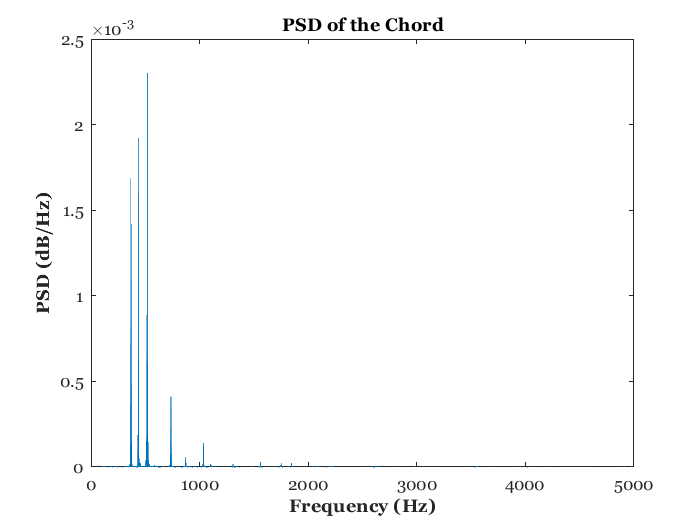

% Now let's inspect what the periodogram( ) function returns...
[PSD, f] = periodogram(SoundData, [], [], fs);

% Now let's plot the result...
plot(f, PSD)
%plot(f, 10*log10(PSD))
title('\bf\fontname{Georgia}PSD of the Chord')
xlabel('\bf\fontname{Georgia}Frequency (Hz)')
ylabel('\bf\fontname{Georgia}PSD (dB/Hz)')
set(gca,'Fontname', 'Georgia');
xlim([0 5e3])

As can hopefully be seen, there seems to be three, tall spikes, representing (I'd think) the fundamental tones, and this makes sense as a lot of chords are composed of three notes or keys. As well as that, however, we can see spikes at integer multiples of each of these fundamental tones - these are the harmonics! Lastly, what this plot shows us is that the power spectral density is highest at the fundamental tones... this sort of makes sense, as *these* are the notes that are actually being played after all. Okay, let's now plot the signal in the time domain:

Ts = 1/fs; % The sampling period...
t_vector = Ts:Ts:numel(SoundData)*Ts % The time vector...

t_vector =     0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010


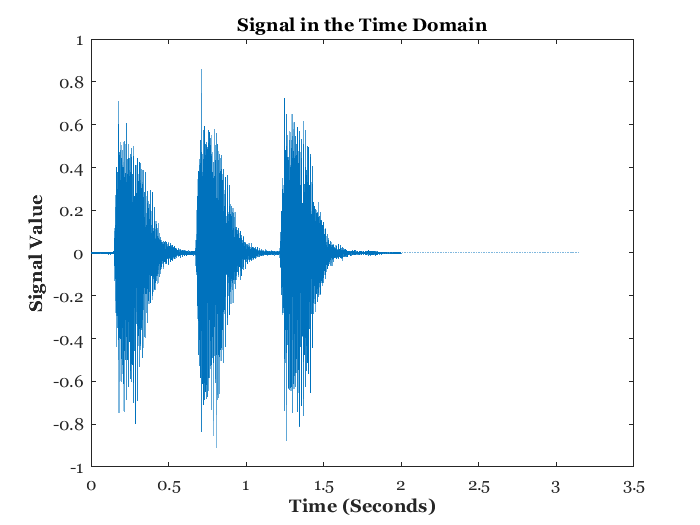


plot(t_vector, SoundData)
title('\bf\fontname{Georgia}Signal in the Time Domain')
ylabel('\bf\fontname{Georgia}Signal Value')
xlabel('\bf\fontname{Georgia}Time (Seconds)')
set(gca,'Fontname', 'Georgia');

The graph seems consistent with what we heard earlier! The chord is played 3 times, as indicated by the 3 blue, spikey blobs towards the left. They all have the same shape, more or less, as it's the same chord being played. They also all last for more or less the same amount of time, reflecting the fact that the player didn't hold down any chord for longer, the tempo was fixed. Returning, momentarily, to the output that the periodogram( ) command gave: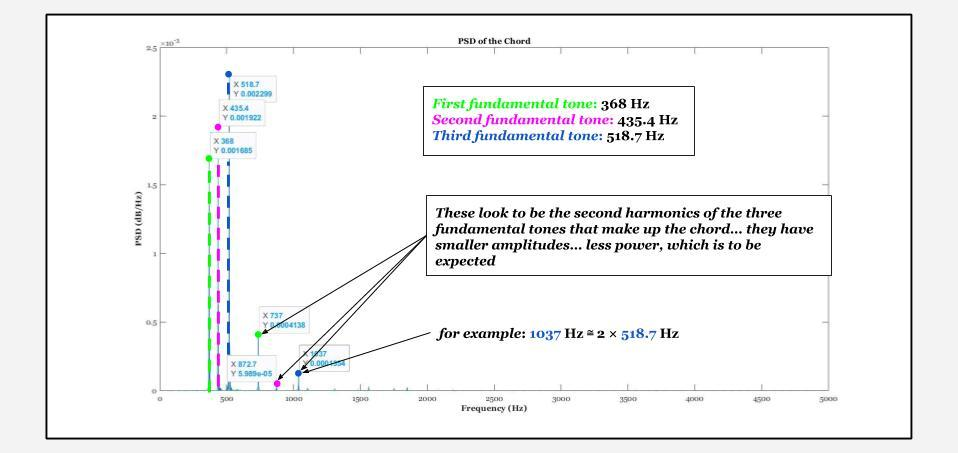

As is hopefully clear from the above, we seem to have 3 fundamental tones with frequencies: 368 Hz, 435.4 Hz, and 518.7 Hz. Consulting online resources, it seems that the keys that are most likely comprising the chord are: F#4 369 Hz, A4 440 Hz, and C5 523 Hz. Plugging in my now-dusty digital piano, and playing the chord, it seems we're most likely right, as it sounds the same as that which we heard earlier on! Also, if one looks closely, they'll see more smaller peaks towards the right: these correspond to the higher-order harmonics (3f, 4f, 5f etc.)

**Implementing Welch's Method:**

Welch's method involves averaging the periodograms of overlapping sequences. As a result, our first task is to essentially break up our sequence into smaller overlapping ones. I'm also going to use a 50% overlap, as it tends to be a very commonly used one... probably because as the percentage overlap gets closer to 0%, we basically get Bartlett's method, which isn't as accurate... the overlapping essentially compensates for the fact that the application of the window to each subsequence reduces or tapers the ends points. I've shown below the approach I'll be taking towards parsing the sequence up... I've used a smaller, 16-sample one, but the idea is the same:

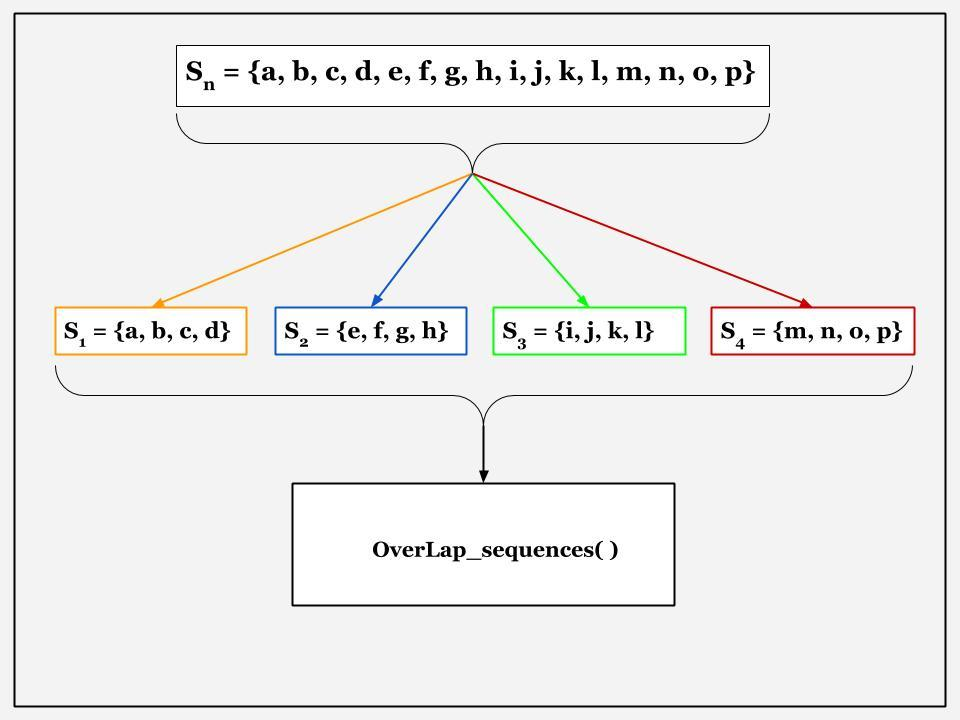

Now, once we've got those sequences, we'll put them through a function which will overlap them as needed. Hopefully the diagram below gives a slightly better idea:

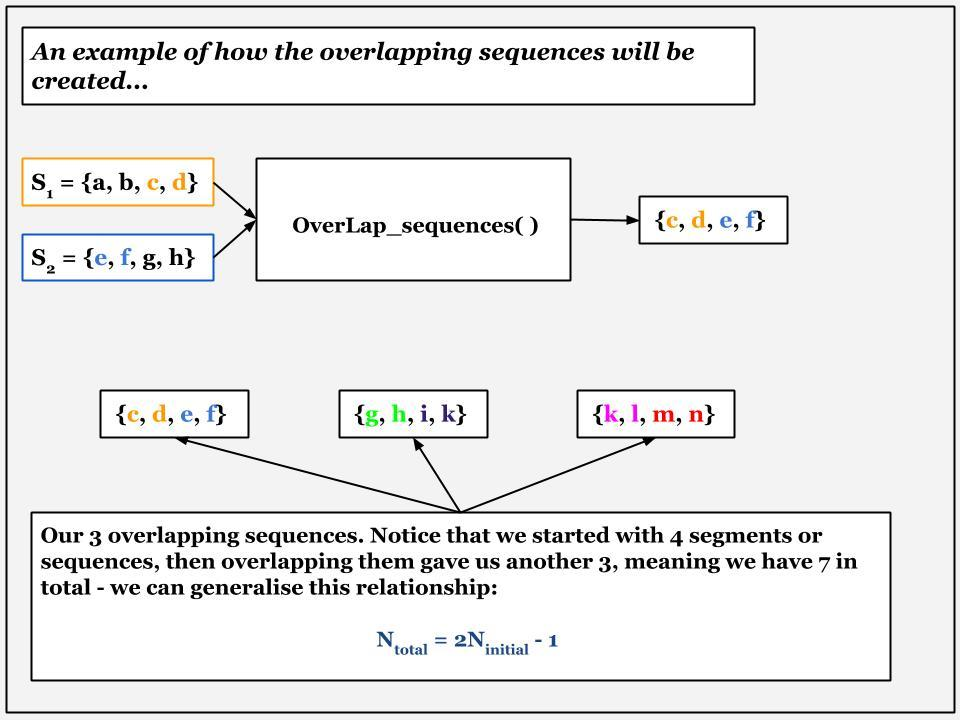

*In relation to the formula mentioned at the end of the above diagram, it should be pointed out that it assumes we're using a** 50%** overlap. Also, the Overlap_sequences( ) function needs the two vectors to have an even number of elements: this is easy to do, we simply split the original sequence into subsequences with an even number of elements in each. Now it's time to try and code in some of these ideas!

[SoundData, fs] = audioread('17734349.wav')

SoundData =          0
   -0.0000
   -0.0000
   -0.0000
         0
   -0.0000
   -0.0000
         0
   -0.0000
   -0.0000


fs = 48000


OverLap_factor = 0.5; % The overlap factor for each segment... 50 % seems
% to be the most commonly used...

S_n = SoundData; % The sequence... this reassignment to the variable S_n admittedly isn't necessary
% but I did it merely to be consistent with the above diagram - also, the
% 'cost' of such a reassignment in this situation is negligible...

Num_segs = 40; % The number of segments we'll have... a number which divides nicely
% into the number of data points we have... this represents N_initial
% mentioned in the above diagram or illustration...
Index_Vector = 1:numel(S_n)/Num_segs:1+(Num_segs-1)*numel(S_n)/Num_segs % This index vector

Index_Vector =            1        3773        7545       11317       15089       18861       22633       26405       30177       33949       37721       41493       45265       49037       52809       56581       60353       64125       67897       71669       75441       79213       82985       86757       90529       94301       98073      101845      105617      109389      113161      116933      120705      124477      128249      132021      135793      139565      143337      147109


% will be very important in a moment or two... it represents the row
% indices where we'll place our initials sequences (N_initial), shown in
% the diagram above...
SegmentStorage_matrix = zeros(Num_segs, numel(S_n)/Num_segs); 

for row = 1:1:Num_segs
    SegmentStorage_matrix(row, :) = S_n(Index_Vector(row):Index_Vector(row) + numel(S_n)/Num_segs -1);
end

Big_matrix = zeros(2*Num_segs - 1, numel(S_n)/Num_segs); % This 'Big' matrix will also
% include the sequences formed by overlapping the segments in the
% SegmentStorage_Matrix

for k = 0:1:Num_segs - 1
    Big_matrix(2*k + 1, :) = SegmentStorage_matrix(k + 1, :);
end

for k = 1:Num_segs - 1
    % We are now creating those overlapping sequences by considering the
    % sequences in the odd index positions... the function doing the
    % overlapping is OverLap_Sequences( ), as was shown in the diagram
    % earlier on
    Big_matrix(2*k, :) = OverLap_Sequences(Big_matrix(2*k - 1, :), Big_matrix(2*k + 1, :), OverLap_factor);
end

Window_Coefficients = hann(numel(S_n)/Num_segs); % The Hanning window coefficient vector:
% it, of course, has the same number of elements as each of our
% segments...

% Now we're going to create another 'Big' matrix, whose rows will be the
% same as those in the first 'Big' matrix, except they'll all have the
% Hanning window applied to them - this step is therefore the windowing
% phase...
Big_matrix2 = Big_matrix.*Window_Coefficients';

% The third and final 'Big' matrix
Big_matrix3 = fft(Big_matrix2'); % We take the tranpose of the Big_matrix2 as the fft( )
% function works on the columns of the input matrix... so we need to switch
% the rows and columns so that the fft( ) is applied correctly...
Big_matrix3 = Big_matrix3'.^2; % Lastly, let's square all the elements in accordance with
% the description of Welch's method... and also take transpose of the
% matrix, to return it to its earlier form...

for i = 1:2*Num_segs - 1 
    Big_matrix3(i, :) = Big_matrix3(i, :).*(1/i); % Multiplying the ith periodogram by 1/i...
end

PSD_est = sum(Big_matrix3, 1).*(1/(2*Num_segs - 1)); % Calculating the average of all the periodograms

Average_Window_Power = sum(Window_Coefficients.^2).*1/numel(Window_Coefficients); % The average power of the
% Hanning window...

PSD_est = PSD_est.*(1/Average_Window_Power).*(1/(2*pi*fs)); % Finally dividing the average
% of the periodograms by the average window power as well as the sampling
% frequency...

% Let us also see what the pwelch( ) function gives...
[Pxx, f] = pwelch(S_n, Window_Coefficients, [], [], fs)

Pxx = 	1.0e+-3 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0000
    0.0001


f = 	1.0e+04 *

         0
    0.0012
    0.0023
    0.0035
    0.0047
    0.0059
    0.0070
    0.0082
    0.0094
    0.0105


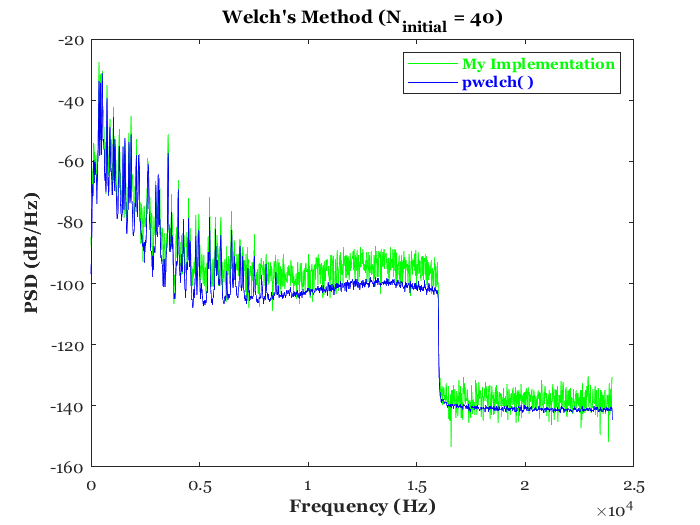

Pxx = Pxx.*(1/Average_Window_Power); % A necessary step as it seems MatLab by default doesn't do this...

freq_Vec = (fs*Num_segs/numel(S_n)).*[0:numel(S_n)/Num_segs - 1]; % For plotting purposes...

plot(freq_Vec(1:(numel(S_n)/Num_segs)/2), 10*log10(abs(PSD_est(1:(numel(S_n)/Num_segs)/2))), 'color', 'g')
Title1 = sprintf('Welch''s Method (N_{initial} = %i)', Num_segs);
title(Title1)
ylabel('\bf\fontname{Georgia}PSD (dB/Hz)');
xlabel('\bf\fontname{Georgia}Frequency (Hz)');
set(gca,'Fontname', 'Georgia');

hold on

plot(f, 10*log10(Pxx), 'color', 'b')
legend({'\bf\fontname{Georgia}\color{green}My Implementation','\bf\fontname{Georgia}\color{blue}pwelch( )'},'Location','northeast','Orientation','vertical'); % Just adding
% a legend for clarity...

hold off

As can seen, both curves or PSDs have largely the same shape, there's a minor offset. In order to investigate if this is related to the number of overlapping sequences we initially chose, I've attached graphs: 1 showing the same graph when Num_segs = 80, and another when it's 20: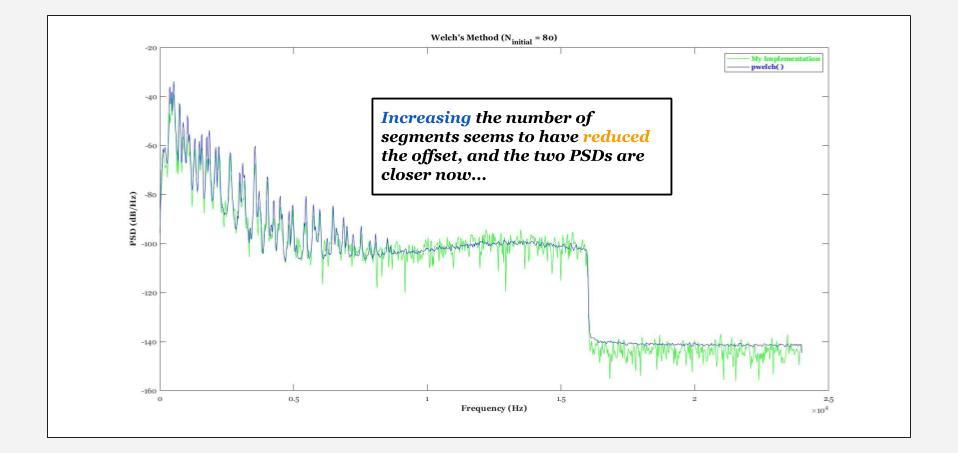

Increasing the number of initial segments seems to have made our PSD follow the output from the pwelch( ) command more closely... Let's check what happens when the number of segments at the beginning (before performing the 50% overlapping) is 20:

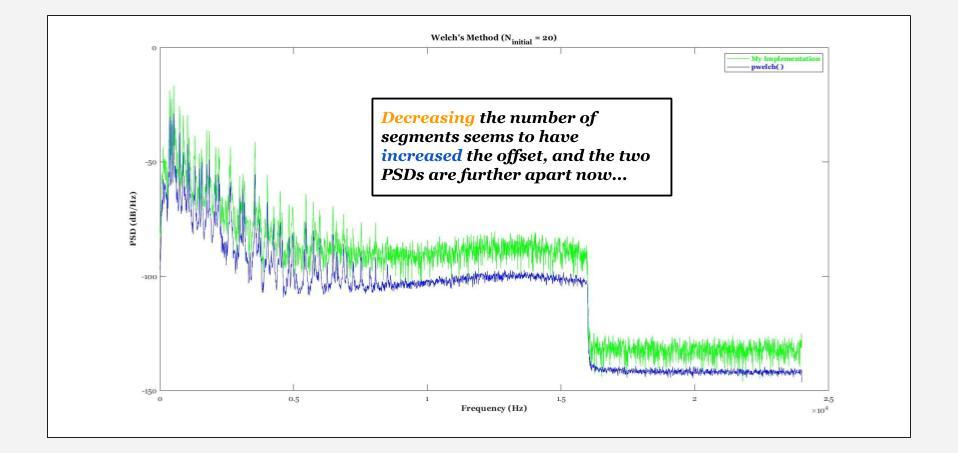

The offset seems to have gotten worse...

**(Task 2) AR Model Estimation:**

**(Q3) (a) and (b):** Let's generate some samples of the random signal:

N = 1000; % The number of samples of the random signal we'll take...
x_n = generateSignal(17734349, N); % We'll have 1000 samples...

Now let's look at the equation which we'll use to estimate the autocorrelation function:


$$\hat{r} \left(k\right)=\frac{1}{N}\sum_{n=0}^{N-k-1} x_n x_{n+k} ,\;\;\;\textrm{where}\;k=0,1,2,3\;\ldotp \ldotp \ldotp ,N-1$$


Let's try and put the above idea into code...

p = 6; % A test value for p... the user can change it if they like...

r_k = zeros(1, N); % The empty autocorrelation vector...

for k = 0:p
    sum_count = 0;
    for n = 0:N-1-k
        sum_count = sum_count + x_n(n+1)*x_n(n+1+k);
    end
    r_k(k+1) = sum_count;
end

r_k = r_k.*(1/N) % Laslty, divide each element by the number of elements (N)...

r_k =   137.1927  127.4676  101.5515   66.1885   28.8664   -4.0152  -28.1104  -41.4748  -44.4673  -39.1396  -28.5422  -15.8104   -3.4621    6.8504   14.1479   18.0324   18.6313   16.6488   13.2727    9.8207    7.2391    6.0565    6.4554    8.2335   10.7048   12.7819   13.5313   12.5191    9.9755    6.6045    3.2539    0.7446   -0.3856    0.0029    1.6347    3.7681    5.4262    5.8881    4.8512    2.3408   -1.2444   -5.2168   -8.5976  -10.2478   -9.1819   -4.9748    1.9227   10.2801   18.4675   24.8269



r = xcorr(x_n) % Here we're making use of the xcorr( ) command...

r = 	1.0e+05 *

    0.0000
    0.0001
   -0.0003
   -0.0015
   -0.0033
   -0.0054
   -0.0073
   -0.0086
   -0.0086
   -0.0075


r = r.*(1/N) % The function doesn't do this part, hence why we're doing it ourselves here...

r =     0.0039
    0.0071
   -0.0327
   -0.1502
   -0.3330
   -0.5417
   -0.7293
   -0.8556
   -0.8638
   -0.7549



k_vector = 0:p % This vector is for plotting purposes...

k_vector =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


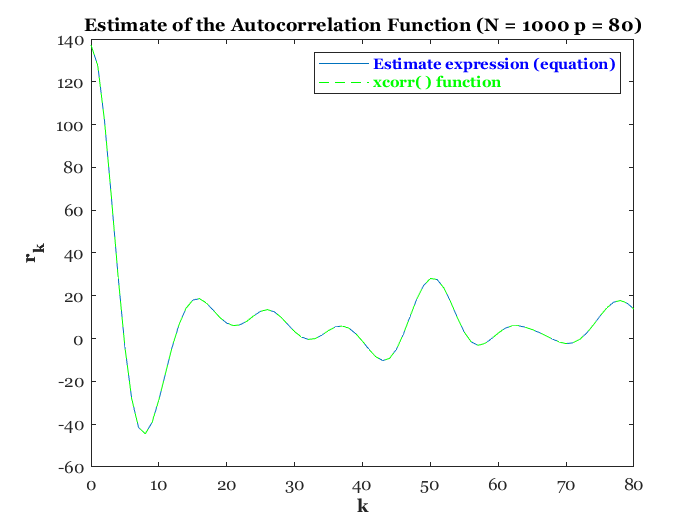


plot(k_vector, r_k(1:p+1))
Title_text = sprintf('Estimate of the Autocorrelation Function (N = %i p = %i)', N, p);
title(Title_text)
ylabel('\bf\fontname{Georgia}r_{k}');
xlabel('\bf\fontname{Georgia}k');
set(gca,'Fontname', 'Georgia');

hold on

% Now, it turns out that xcorr( ) returns a 2-sided version of the
% autocorrelation function: as a result, we simply take the righthand
% side... it should be said that it's symmetrical about the centre
% index, which is N... hence why we start from index N when plotting the
% graph below. ALso, if one scrolls up to where the xcorr( ) function was
% invoked, they can see that it returns 2N-1 elements...
plot(k_vector, r(N:N+p), 'LineStyle', '--', 'color', 'g')
legend({'\bf\fontname{Georgia}\color{blue}Estimate expression (equation)','\bf\fontname{Georgia}\color{green}xcorr( ) function'},'Location','northeast','Orientation','vertical'); % Just adding

hold off

As can be seen, the two match up more or less perfectly... even when the values for N and p are changed, the two stay in line with one another!

**(c) **Now we'll try and compute the sequence of a's:

cross_corr_vector = r_k(2:p+1)' % Our cross-correlation vector... we're taking its transpose merely

cross_corr_vector =   127.4676
  101.5515
   66.1885
   28.8664
   -4.0152
  -28.1104
  -41.4748
  -44.4673
  -39.1396
  -28.5422


% so we can use the '\' operator to solve the matrix equation below...

% Now we need to form the 'R' matrix - we'll use our autocorrelation vector
% as well as the toeplitz( ) function...
R = toeplitz(r_k(1:p)); % This forms the autocorrelation matrix very nicely...

% Now we can work out the coefficients as follows:
a_coefficients = -R\cross_corr_vector % This is in accordance with the formula in the lecture notes...

a_coefficients =    -2.1866
    1.7616
   -0.5289
    0.0095
    0.0225
    0.0498
   -0.1193
    0.1416
   -0.1313
    0.0745


As for the noise power, it is given by the following equation:


$$\sigma^2 =r\left(0\right)+\sum_{i=1}^{i=p} a_i r\left(i\right)$$


With the above in mind, let us try and work out the noise power...

sigma_squared = 0; % Say initially it's 0...

for i = 1:p
    sigma_squared = sigma_squared + a_coefficients(i)*r_k(i+1);
end

sigma_squared = sigma_squared + r_k(1) % This simply adds the first element of our

sigma_squared = 2.6204

% autocorrelation vector, shown as r(0) in the equation above...

(d) Now we can use the following expression to estimate the PSD of the signal:


$$\textrm{PSD}=\sigma^2 \left|H\left(\omega \right){\left|\right.}^2 \right.$$


We've just worked out the noise power ($\sigma^2$), but what about the transfer function? We can form it using the coefficients (sequence of a's) we've just worked out:


$$H\left(\omega \right)=\frac{1}{1+a_1 z^{-1} +a_2 z^{-2} +a_3 z^{-3} \ldotp \ldotp \ldotp +a_p z^{-p} }$$


In regards to the above expression for the transfer function, the numerator is 1 as we only have one *b *coefficient - *b *= {1}. Let us now put the above idea into code:

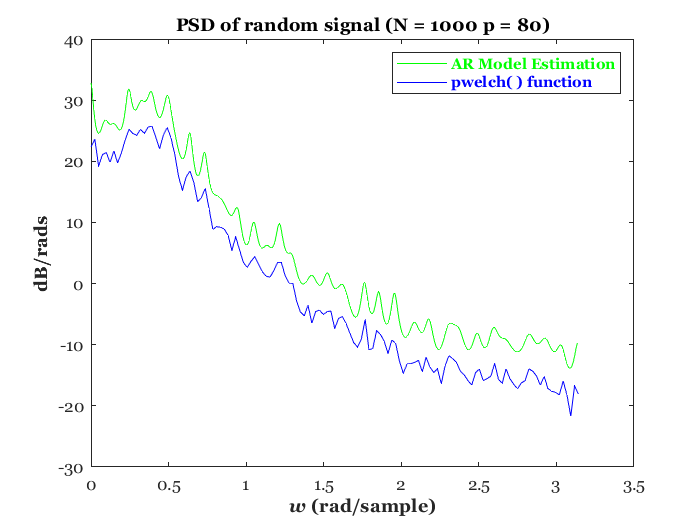

Denom = [1 a_coefficients']; % The denominator of our transfer function... in the z-domain...
Num = 1; % The numerator...
[H, w] = freqz(Num, Denom); % Working out the frequency response, given the numerator and denominator expressions we have...

PSD = sigma_squared*(abs(H).^2); % This corresponds to the expression I gave above for the PSD estimate...

[Pxx2, w2] = pwelch(x_n); % Using the pwelch( ) function for comparison...

plot(w, 10*log10(PSD), 'color', 'g') % We're going to plot in dB/Hz or dB/rads hence the 10*log10( )...
Title_text = sprintf('PSD of random signal (N = %i p = %i)', N, p);
title(Title_text)
ylabel('\bf\fontname{Georgia}dB/rads');
xlabel('\bf\fontname{Georgia}\itw \rm\bf(rad/sample)');
set(gca,'Fontname', 'Georgia');

hold on

plot(w2, 10*log10(Pxx2), 'color', 'b') % Plotting the result from the pwelch( ) command...
legend({'\bf\fontname{Georgia}\color{green}AR Model Estimation','\bf\fontname{Georgia}\color{blue}pwelch( ) function'},'Location','northeast','Orientation','vertical');
 
hold off

As can be seen, the two have the same general shape, although there's an offset present.

**(Q4) **Let's now alter the values for N and p and see the effect they have on the PSD. It makes sense, I think, to try and establish the upper and low bounds of the spectrum of behaviour: let's keep N fixed and make p very large; then let's keep p fixed and make N very small...

**Case 1: N = 200, p = 6 (The user can scroll up and change these values for themselves too!)**

When I decreased the value of N to 200, the following things were observed:


$$\begin{array}{l}
\longrightarrow \mathrm{The}\;\mathrm{autocorrelation}\;\mathrm{estimate}\;\mathrm{still}\;\mathrm{matched}\;\mathrm{perfectly}\;\mathrm{with}\;\mathrm{the}\;\mathrm{xcorr}\left(\;\right)\;\mathrm{function}\\
\longrightarrow \mathrm{The}\;\mathrm{noise}\;\mathrm{power}\;\mathrm{increased}\\
\longrightarrow \mathrm{The}\;\mathrm{AR}\;\mathrm{model}\;\mathrm{estimation}\;\mathrm{became}\;\mathrm{weaker}-\mathrm{see}\;\mathrm{the}\;\mathrm{graph}\;\mathrm{below}
\end{array}$$


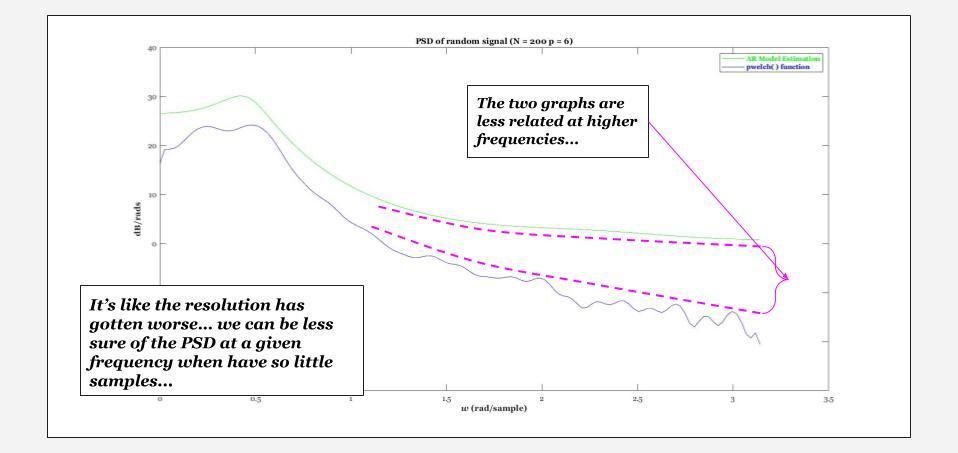

**Case 2: N = 1000, p = 30**

When I set the parameters as shown above, I noted the following:

$\begin{array}{l}
\longrightarrow \mathrm{The}\;\mathrm{autocorrelation}\;\mathrm{estimate}\;\mathrm{still}\;\mathrm{matched}\;\mathrm{perfectly}\;\mathrm{with}\;\mathrm{the}\;\mathrm{xcorr}\left(\;\right)\;\mathrm{function}\\
\longrightarrow \mathrm{The}\;\mathrm{noise}\;\mathrm{power}\;\mathrm{decreased}\\
\longrightarrow \mathrm{The}\;\mathrm{AR}\;\mathrm{model}\;\mathrm{estimation}\;\mathrm{became}\;\mathrm{stronger}\;\mathrm{or}\;\mathrm{better}-\mathrm{see}\;\mathrm{the}\;\mathrm{graph}\;\mathrm{below}
\end{array}$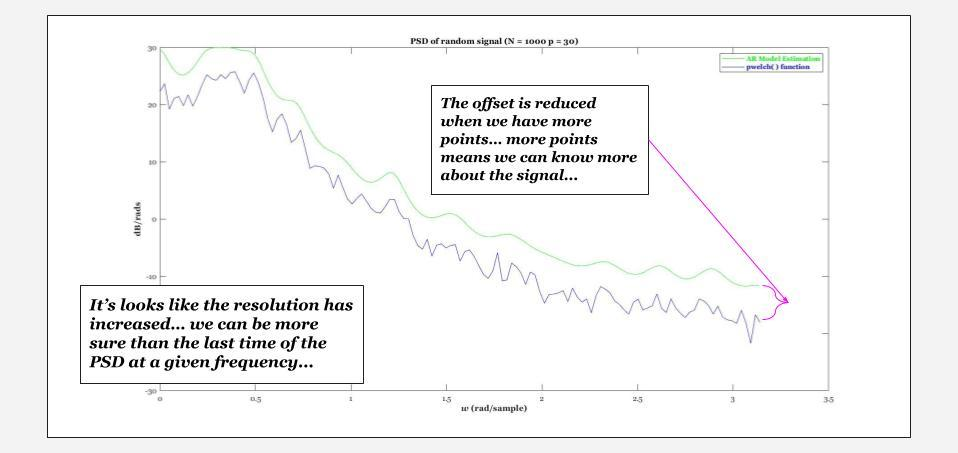

I haven't included the graph, but keeping N fixed, and increasing p, I noticed that the offset continued getting smaller and smaller, and our estimation became more and more in line with the pwelch( ) command. 

**(Q5) **Laslty, let's investigate something that I pondered while looking at the expression for autocorrelation estimation, namely that the summing of x_n*x_(n+k) looks similar to the convolution! 

n = 10;
x = generateSignal(123, n)

x =    -0.1978
   -2.0241
    4.5771
   -4.4826
    0.8071
    2.9525
   -4.4792
    3.8550
   -1.7451
    1.1328


r = conv(x, x(end:-1:1))/n

r =    -0.0224
   -0.1948
    0.7955
   -1.9982
    3.4864
   -4.1982
    2.5730
    1.8578
   -6.9812
    9.3800



% Now let's use our method from earlier and see if it gives us the same:
N = numel(x) % This will be used in the for loop...

N = 10


for k = 0:N-1
    sum_count = 0;
    for Idx = 0:N-1-k
        sum_count = sum_count + x(Idx+1)*x(Idx+1+k);
    end
    r_k(k+1) = sum_count;
end

r_k = r_k.*(1/N) % Like last time, we divide by the number of elements...

r_k =     9.3800   -6.9812    1.8578    2.5730   -4.1982    3.4864   -1.9982    0.7955   -0.1948   -0.0224         0         0         0         0         0         0         0         0         0         0


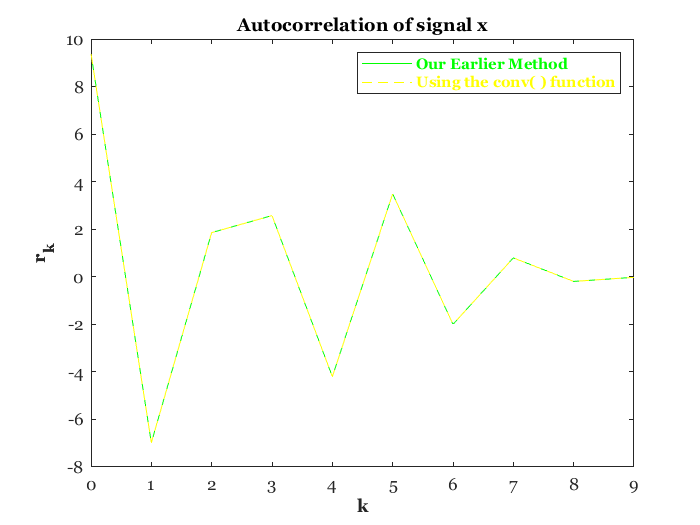


plot(0:9, r_k(1:10), 'color', 'g')
Title_text = sprintf('Autocorrelation of signal x');
title(Title_text)
ylabel('\bf\fontname{Georgia}r_{k}');
xlabel('\bf\fontname{Georgia}k');
set(gca,'Fontname', 'Georgia');


hold on

plot(0:9, r(N:end), 'color', 'y', 'LineStyle','--')
legend({'\bf\fontname{Georgia}\color{green}Our Earlier Method','\bf\fontname{Georgia}\color{yellow}Using the conv( ) function'},'Location','northeast','Orientation','vertical');

As for why this can be done, let's just quickly look at what the first expression becomes if one writes it out: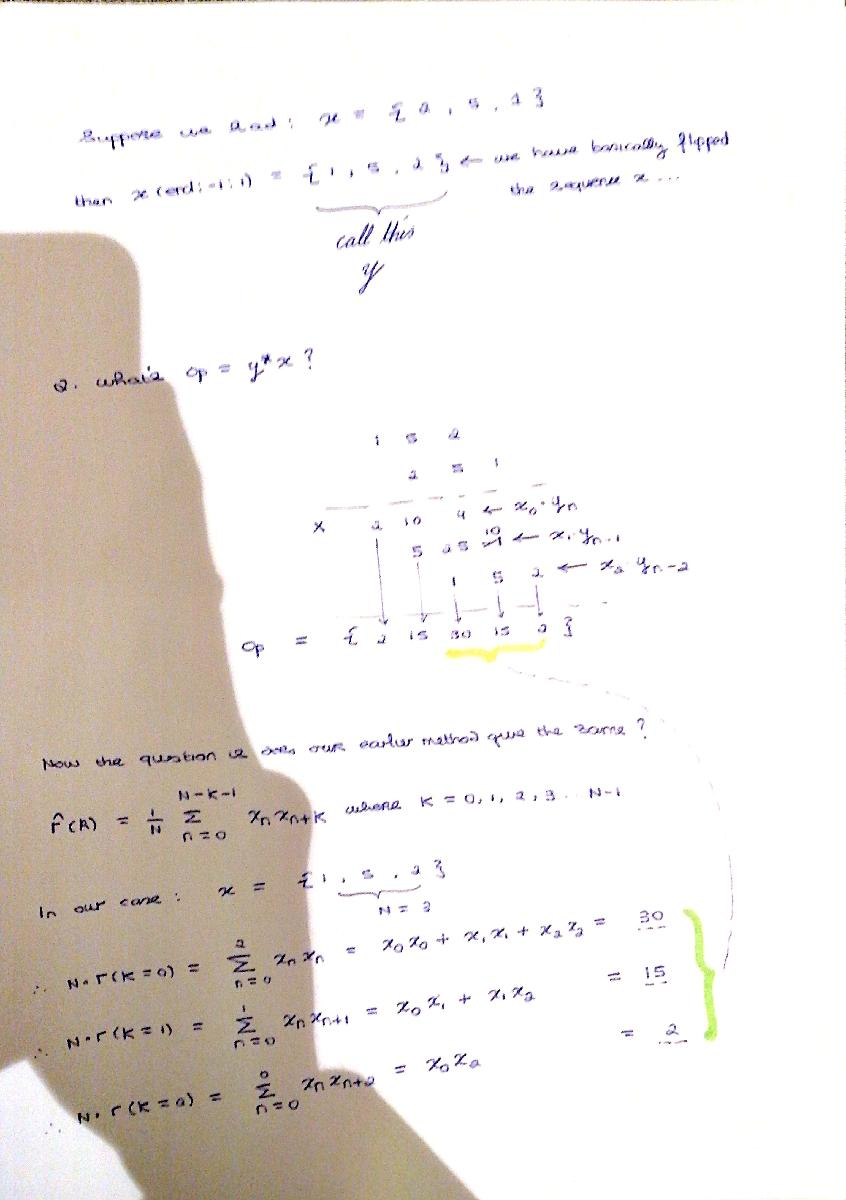

When both of the above sequences are divided by N, they'll still contain the same numbers and pattern - moreover, this could be generalised for sequences much bigger than 3 samples (like our case of 10 samples), I simply chose 3 so as to get the point across without having to do loads of calculations. It can also be seen that the convolution method returns a 2-sided autocorrelation, like the xcorr( ) function...

function Resultant_Sequence = OverLap_Sequences(SeqA, SeqB, OL_factor)

Resultant_Sequence = zeros(1, numel(SeqA)); % Initialising the Resultant sequence...

% Now let's fill in the sequence with the relevant values...
Resultant_Sequence(1:numel(SeqA)*OL_factor) = SeqA(numel(SeqA)*OL_factor + 1:2*numel(SeqA)*OL_factor);
Resultant_Sequence(numel(SeqA)*OL_factor + 1:2*numel(SeqA)*OL_factor) = SeqB(1:numel(SeqA)*OL_factor);
end